# Ecoli core model

% clear all, clc;
% changeCobraSolver('ibm_cplex');
% addpath([pwd,'\Vizualization'])

## load model and check basic properties

ecoli=readCbModel('Model\ecoli_core_model.mat');
% model=ecoli;
% %model pathways
% Pathways=unique([model.subSystems])
% disp(['Model contains ' num2str(length(Pathways)) ' pathways'])
% 
% disp('Model objective function:')
% %find objective function
% ObjF=find(model.c);
% disp(model.rxns(ObjF))%biomass function is objective function by default
% %check biomass composition
% ObjFCoefs=model.S(:,ObjF);
% MetsIndxObjF=find(model.S(:,ObjF));
% [{'-' 'Biomass Comp.'}; model.mets(MetsIndxObjF) num2cell(ObjFCoefs(find(ObjFCoefs)))]
% % solverOK = changeCobraSolver('glpk');

## find exchange reactions -- list metabolites that are uptaken and/or

## secreted

% [selExc, selUpt] = findExcRxns(model);
% model.rxns(selExc)
% model.rxns(selUpt)

## a) Investigate two di?fferent conditions (aerobic ! anaerobic) by setting the bounds for oxygen

exchange appropriately. What are the main di?erences? Provide e.g. table(s) (highlight the di?erences) and ?gures to justify your answer.

## Aerobic growth on glucose

model=ecoli;
modelGlc = model;
modelGlc = changeRxnBounds(modelGlc,'EX_glc(e)',-18.5,'l');
modelGlc = changeRxnBounds(modelGlc,'EX_o2(e)',-1000,'l');
modelGlc=changeObjective(modelGlc,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');
FBAsolutionGlc = optimizeCbModel(modelGlc,'max');

map = readCbMap('Ecoli_core_map.txt');
drawFlux(map,modelGlc,FBAsolutionGlc.x,[],'FileName','ecoli_aerobic.svg','ZeroFluxWidth',1,'lb',-15,'ub',15,'edgeWeight',20)

Document Written


ans = struct with fields:
            fileName: 'ecoli_aerobic.svg'
       zeroFluxWidth: 1
                  lb: -15
                  ub: 15
          edgeWeight: [476×1 double]
          colorScale: [100×3 double]
           scaleType: 1
    rxnDirMultiplier: 2
      scaleTypeLabel: 'Linear;'
           overlayUB: '15+'
           overlayLB: '-15-'
           edgeColor: [476×3 double]
         overlayType: 'Flux'



% options.lb=-30;
% options.ub=30;
% options.zeroFluxWidth = 0.1;
% options.rxnDirMultiplier = 10;
% options.edgeWeight=20;
% options.zeroFluxColor = [217 217 217]; %reactions with 0 flux are grey (RGB code)
% options.fileName='EcoliGlcO2.svg'; %file name of generated svg file
% options = drawFlux(map,modelGlc,FBAsolutionGlc.x,options); %function that places the fluxes (solution.x) on top of the map file and renders edges colored by the flux value

## Anaerobic growth on glucose

modelGlcAnaer = changeRxnBounds(modelGlc,'EX_o2(e)',0,'l');
FBAsolutionGlcAnaer = optimizeCbModel(modelGlcAnaer,'max');

drawFlux(map,modelGlcAnaer,FBAsolutionGlcAnaer.x,[],'FileName','ecoli_anaerobic.svg','ZeroFluxWidth',1,'lb',-15,'ub',15,'edgeWeight',20)

Document Written


ans = struct with fields:
            fileName: 'ecoli_anaerobic.svg'
       zeroFluxWidth: 1
                  lb: -15
                  ub: 15
          edgeWeight: [476×1 double]
          colorScale: [100×3 double]
           scaleType: 1
    rxnDirMultiplier: 2
      scaleTypeLabel: 'Linear;'
           overlayUB: '15+'
           overlayLB: '-15-'
           edgeColor: [476×3 double]
         overlayType: 'Flux'



% options.zeroFluxWidth = 0.1;
% options.rxnDirMultiplier = 10;
% options.zeroFluxColor = [217 217 217]; %reactions with 0 flux are grey
% options.fileName='EcoliGlcAnaer.svg';
% options = drawFlux(map,modelGlcAnaer, FBAsolutionGlcAnaer.x,options);

## b) In anaerobic conditions, in order to obtain the same growth rate as aerobic conditions, how much more glucose would have to be provided?

model=ecoli;
model=changeRxnBounds(model,'EX_o2(e)',0,'l'); %set the anaerobic condition
BOF_indx=find(ismember(model.rxns,'Biomass_Ecoli_core_N(w/GAM)-Nmet2'));
model=changeRxnBounds(model,model.rxns(BOF_indx),FBAsolutionGlc.f,'b'); %fix the biomass rate from the aerobic condition
model=changeRxnBounds(model,'EX_glc(e)',-1000,'l');

% model=changeObjective(model,'EX_glc(e)');
solutionAnaerBOFAer=optimizeCbModel(model,'max');



printFluxVector(model, solutionAnaerBOFAer.x, true); %only print non-zero fluxes

ACALD               	      -43.89
ACKr                	      -45.64
ACONTa              	       1.783
ACONTb              	       1.783
ACt2r               	      -45.64
ALCD2x              	      -43.89
ATPM                	        8.39
ATPS4r              	      -37.39
Biomass_Ecoli_core_N(w/GAM)-Nmet2	       1.653
CO2t                	       2.954
CS                  	       1.783
ENO                 	       107.8
ETOHt2r             	      -43.89
EX_ac(e)            	       45.64
EX_co2(e)           	      -2.954
EX_etoh(e)          	       43.89
EX_for(e)           	        97.5
EX_glc(e)           	      -57.32
EX_h2o(e)           	       -34.8
EX_h(e)             	       176.3
EX_nh4(e)           	      -9.014
EX_pi(e)            	      -6.081
FBA                 	       55.68
FORti               	        97.5
GAPD                	       110.3
GLCpts              	       57.32
GLNS                	      0.4227
GLUDy               	      -8.591
H2Ot                	        34.8
I

printFluxVector(model, solutionAnaerBOFAer.x, true, true); %only print exchange non-zero fluxes

EX_ac(e)            	       45.64
EX_co2(e)           	      -2.954
EX_etoh(e)          	       43.89
EX_for(e)           	        97.5
EX_glc(e)           	      -57.32
EX_h2o(e)           	       -34.8
EX_h(e)             	       176.3
EX_nh4(e)           	      -9.014
EX_pi(e)            	      -6.081


%answer
Glc_ex_indx=find(ismember(model.rxns,'EX_glc(e)'));
Amount=solutionAnaerBOFAer.x(Glc_ex_indx)/FBAsolutionGlc.x(Glc_ex_indx)

Amount = 3.0985

## comment the 3 solutions

cell2table([model.rxns num2cell(FBAsolutionGlc.x) num2cell(FBAsolutionGlcAnaer.x) num2cell(solutionAnaerBOFAer.x)],'VariableNames',{'ModelReactions','Aerobic','Anaerobic','AnaerobicBiomass'})

ans = 95×4 table
               ModelReactions                Aerobic    Anaerobic    AnaerobicBiomass
    _____________________________________    _______    _________    ________________

    {'ACALD'                            }          0     -14.675         -43.885     
    {'ACALDt'                           }          0           0               0     
    {'ACKr'                             }          0     -15.173         -45.636     
    {'ACONTa'                           }     10.366     0.50769          1.7835     
    {'ACONTb'                           }     10.366     0.50769          1.7835     
    {'ACt2r'                            }          0     -15.173         -45.636     
    {'ADK1'                             }          0           0               0     
    {'AKGDH'                            }     8.5822           0        

## check if the value obtained for glucose uptake gives the biomass value

O2_ex_indx=find(ismember(model.rxns,'EX_o2(e)'));


model=changeRxnBounds(model,model.rxns(O2_ex_indx),0,'l'); %negative exchange stands for uptake
model=changeRxnBounds(model,model.rxns(Glc_ex_indx),solutionAnaerBOFAer.f,'l'); %set glucose uptake value to the one obtained before
model=changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');
solTest=optimizeCbModel(model,'max');
solTest.f

ans = 1.6531

%%OK

## c) Calculate the maximal growth rate in the aerobic and anaerobic condition using alternate substrates.

%Set the maximum uptake rate of the respective substrate to 20 mmol gDW-1 hr-1.
%Calculate the maximal growth rate at least for 6 alternative substrates

O2_ex_indx=find(ismember(model.rxns,'EX_o2(e)'));

% carbon sources
substrates={'EX_ac(e)','EX_acald(e)','EX_akg(e)','EX_etoh(e)','EX_fru(e)','EX_fum(e)','EX_glc(e)','EX_gln_L(e)','EX_glu_L(e)','EX_lac_D(e)','EX_mal_L(e)','EX_pyr(e)','EX_succ(e)'};
res=zeros(length(substrates),2);
for i=1:length(substrates)
    cur_sub=substrates(i);
    model=ecoli;
    model = changeRxnBounds(model,'EX_glc(e)',0,'l');
    
    %aer
    model=changeRxnBounds(model,model.rxns(O2_ex_indx),-1000,'l');
    model=changeRxnBounds(model,cur_sub,-20,'l');
    solaer=optimizeCbModel(model);
    res(i,1)=[solaer.f];% sol.x(13) = sol for biomass

    %anaer
    model=changeRxnBounds(model,model.rxns(O2_ex_indx),0,'l');
    solanaer=optimizeCbModel(model);
    res(i,2)=[solanaer.f ];
end


tab=[substrates' num2cell(res)];
tab=[{'substrate' 'Aer' 'Anaer'};tab]

tab = 14×3 cell array
    {'substrate'  }    {'Aer'   }    {'Anaer' }
    {'EX_ac(e)'   }    {[0.3893]}    {[   NaN]}
    {'EX_acald(e)'}    {[0.6073]}    {[     0]}
    {'EX_akg(e)'  }    {[1.0982]}    {[   NaN]}
    {'EX_etoh(e)' }    {[0.6996]}    {[   NaN]}
    {'EX_fru(e)'  }    {[1.7906]}    {[0.5163]}
    {'EX_fum(e)'  }    {[0.7865]}    {[   NaN]}
    {'EX_glc(e)'  }    {[1.7906]}    {[0.5163]}
    {'EX_gln_L(e)'}    {[   NaN]}    {[   NaN]}
    {'EX_glu_L(e)'}    {[   NaN]}    {[   NaN]}
    {'EX_lac_D(e)'}    {[   NaN]}    {[   NaN]}
    {'EX_mal_L(e)'}    {[   NaN]}    {[   NaN]}
    {'EX_pyr(e)'  }    {[0.6221]}    {[0.0655]}
    {'EX_succ(e)' }    {[0.8401]}    {[   NaN]}


## d) Calculate the maximum ATP, NADH and NADPH yield from glucose under the aerobic and anaerobic condition.

model=ecoli;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeObjective(model,'ATPM');
model = changeRxnBounds(model,'ATPM',0,'l');
FBAsolutionAerobic = optimizeCbModel(model,'max');
model=changeRxnBounds(model,'EX_o2(e)',0,'l');
FBAsolutionAnaerobic = optimizeCbModel(model,'max');
res=[FBAsolutionAerobic.f,FBAsolutionAnaerobic.f];

model=ecoli;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'b');
model = addReaction(model,'NADH_drain','nadh[c] -> nad[c] + h[c]');
model = changeObjective(model,'NADH_drain');
FBAsolutionAerobic = optimizeCbModel(model,'max');
model=changeRxnBounds(model,'EX_o2(e)',0,'l');
FBAsolutionAnaerobic = optimizeCbModel(model,'max');
res=[res;[FBAsolutionAerobic.f,FBAsolutionAnaerobic.f]];

model=ecoli;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'b');
model = addReaction(model,'NADPH_drain','nadph[c] -> nadp[c] + h[c]');
model = changeObjective(model,'NADPH_drain');
FBAsolutionAerobic = optimizeCbModel(model,'max');
model=changeRxnBounds(model,'EX_o2(e)',0,'l');
FBAsolutionAnaerobic = optimizeCbModel(model,'max');
res=[res;[FBAsolutionAerobic.f,FBAsolutionAnaerobic.f]];

cell2table([{'ATP';'NADH';'NADPH'},num2cell(res)],'VariableNames',{'MaximumProduction','Aerobic','Anaerobic'})

ans = 3×3 table
    MaximumProduction    Aerobic    Anaerobic
    _________________    _______    _________

        {'ATP'  }          8.39       2.75   
        {'NADH' }            10          6   
        {'NADPH'}        8.7778          4   



%%Perform FVA for the two conditions.

## % e+f FVA on Aerobic conditions

model=ecoli; model = changeRxnBounds(model,'EX_glc(e)',-20,'l'); model=changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2'); disp('Flux Variability Analysis (FVA) under AEROBIC conditions') [AerminFlux,AermaxFlux] = fluxVariability(model,90);

[model.rxns num2cell(AerminFlux) num2cell(AermaxFlux)]

## Perform a sampling of the allowed flux distributions for the two conditions.

% With glucose as substrate, do a sampling of allowed fluxes for both aerobic and anaerobic conditions.
%Select 10 reactions for plotting. Calculate correlated reaction sets for both conditions and compare
% results. Are they expected?

## Sampling allowed fluxes for glucose substrate in aerobic conditions

model=ecoli; model_aerobic=changeRxnBounds(model,'EX_glc(e)',-20,'l'); model_aerobic=changeObjective(model_aerobic,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');

sol = optimizeCbModel(model_aerobic); growthRate = sol.f; model_aerobic = changeRxnBounds(model_aerobic,'Biomass_Ecoli_core_N(w/GAM)-Nmet2',0.9*growthRate,'l');

tic % options.nStepsPerPoint = 8 * size(model_aerobic.S, 2); % options.nPointsReturned = 1000; options.nStepsPerPoint = 4 * size(model_aerobic.S, 2); options.nPointsReturned = 1000; options.nWarmupPoints=3000; [modelAerS,samplesAer] = sampleCbModel(model_aerobic,'EcoliAer','ACHR',options); toc %do not include the constant rates for plotting rxns={'PGI', 'PFK', 'FBP', 'FBA', 'TPI', 'GAPD', 'PGK', 'PGM', 'ENO','PYK',model.rxns{find(model.c)}}; sampleScatterMatrix(rxns,modelAerS,samplesAer)

O2_ex_indx=find(ismember(model.rxns,'EX_o2(e)'));

model=ecoli; model = changeRxnBounds(model,'EX_glc(e)',-20,'l');

%aer model=changeRxnBounds(model,model.rxns(O2_ex_indx),-1000,'l'); solaer=optimizeCbModel(model);

%anaer model=changeRxnBounds(model,model.rxns(O2_ex_indx),0,'l'); solanaer=optimizeCbModel(model);

figure; for i = 1 : numel(rxns) subplot(3,4,i) pos=find(ismember(modelAerS.rxns,rxns(i))); hist(samplesAer(pos,:),20); hold on pos=find(ismember(model_aerobic.rxns,rxns(i))); plot([AerminFlux(pos) AerminFlux(pos)], [0 1000],'r','LineWidth',2); plot([AermaxFlux(pos) AermaxFlux(pos)], [0 1000],'r','LineWidth',2); plot([solaer.x(pos) solaer.x(pos)], [0 1000],'y*','LineWidth',2); title(model.rxns{pos}); end legend('Sampling','MinFVA','MaxFVA','FBA') %% Finding modules in metabolic networks [sets,setNumber,setSize]=identifyCorrelSets(modelAerS,samplesAer,1-1e-8); %only 1 set of 5 rxns (v4,v5,v6,O1,O2) for counter=1:size(sets) temp=cell2mat(sets(counter)); disp(['Set ' num2str(counter) ':']) disp([num2cell(temp.set) temp.names]) end % work on saving correl sets results !

%% e+f %% FVA on Anaerobic conditions model=changeRxnBounds(model,model.rxns(O2_ex_indx),0,'l'); disp('Flux Variability Analysis (FVA) under ANAEROBIC conditions') [AnaerminFlux,AnaermaxFlux] = fluxVariability(model,90);

%% Sampling allowed fluxes for glucose substrate in Anaerobic conditions model_anaerobic=changeRxnBounds(model,model.rxns(O2_ex_indx),0,'l'); %negative exchange stands for uptake model_anaerobic=changeRxnBounds(model_anaerobic,'EX_glc(e)',-20,'l'); model_anaerobic=changeObjective(model_anaerobic,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');

sol = optimizeCbModel(model_anaerobic); growthRate = sol.f; model_anaerobic = changeRxnBounds(model_anaerobic,'Biomass_Ecoli_core_N(w/GAM)-Nmet2',0.9*growthRate,'l');

[modelAnaerS,samplesAnaer] = sampleCbModel(model_anaerobic,'EcoliAnaer','ACHR',options);

sampleScatterMatrix(rxns,modelAnaerS,samplesAnaer)

figure; for i = 1 : numel(rxns) subplot(3,4,i) pos=find(ismember(modelAnaerS.rxns,rxns(i))); hist(samplesAer(pos,:),10); hold on pos=find(ismember(model_anaerobic.rxns,rxns(i))); plot([AnaerminFlux(pos) AnaerminFlux(pos)], [0 1000],'r','LineWidth',2); plot([AnaermaxFlux(pos) AnaermaxFlux(pos)], [0 1000],'r','LineWidth',2); plot([solanaer.x(pos) solanaer.x(pos)], [0 1000],'y*','LineWidth',2); title(model.rxns{pos}); end %% Finding modules in metabolic networks [sets,setNumber,setSize]=identifyCorrelSets(modelAnaerS,samplesAnaer,1-1e-8) %only 1 set of 5 rxns (v4,v5,v6,O1,O2) for counter=1:size(sets) temp=cell2mat(sets(counter)); disp(['Set ' num2str(counter) ':']) disp([num2cell(temp.set) temp.names]) end

## e) Determine the growth rate using FBA and the core E. coli metabolic network with the given loss of function mutation of the gene(s) listed for

%each simulation. Then, compare the predictions to the experimental values listed below. Explain your observations. 
%Select one condition where there is a major disagreement between predicted and experimental observations and discuss 
%possible reasons why this occurred.

%ackA
model=ecoli;
model = changeRxnBounds(model,'EX_glc(e)',-10,'l');
model = changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');
[grRatio,grRateKO,grRateWT,~,~] = singleGeneDeletion(model,'FBA',{'b2296'})

Single gene deletion analysis in progress ...
100%    [........................................]


grRatio = 1

grRateKO = 0.8739

grRateWT = 0.8739


model=ecoli;
model = changeRxnBounds(model,'EX_glc(e)',0,'l');
model = changeRxnBounds(model,'EX_lac-D(e)',-20,'l');
model = changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');
[grRatio,grRateKO,grRateWT,~,~] = singleGeneDeletion(model,'FBA',{'b2296'})

Single gene deletion analysis in progress ...
100%    [........................................]


grRatio = 1

grRateKO = 0.7403

grRateWT = 0.7403


model=ecoli;
model = changeRxnBounds(model,'EX_glc(e)',0,'l');
model = changeRxnBounds(model,'EX_akg(e)',-13,'l');
model = changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');
[grRatio,grRateKO,grRateWT,~,~] = singleGeneDeletion(model,'FBA',{'b2296'})

Single gene deletion analysis in progress ...
100%    [........................................]


grRatio = 1

grRateKO = 0.6996

grRateWT = 0.6996


%PCK
model=ecoli;
model = changeRxnBounds(model,'EX_glc(e)',-10,'l');
model = changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');
[grRatio,grRateKO,grRateWT,~,~] = singleGeneDeletion(model,'FBA',{'b3403'})

Single gene deletion analysis in progress ...
100%    [........................................]


grRatio = 1

grRateKO = 0.8739

grRateWT = 0.8739


model=ecoli;
model = changeRxnBounds(model,'EX_glc(e)',0,'l');
model = changeRxnBounds(model,'EX_akg(e)',-13,'l');
model = changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');
[grRatio,grRateKO,grRateWT,~,~] = singleGeneDeletion(model,'FBA',{'b3403'})

Single gene deletion analysis in progress ...
100%    [........................................]


grRatio = 0.9827

grRateKO = 0.6874

grRateWT = 0.6996


%TPI
model=ecoli;
model = changeRxnBounds(model,'EX_glc(e)',-10,'l');
model = changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');
[grRatio,grRateKO,grRateWT,~,~] = singleGeneDeletion(model,'FBA',{'b3919'})

Single gene deletion analysis in progress ...
100%    [........................................]


grRatio = 0.8056

grRateKO = 0.7040

grRateWT = 0.8739


model=ecoli;
model = changeRxnBounds(model,'EX_glc(e)',0,'l');
model = changeRxnBounds(model,'EX_lac-D(e)',-20,'l');
model = changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');
[grRatio,grRateKO,grRateWT,~,~] = singleGeneDeletion(model,'FBA',{'b3919'})

Single gene deletion analysis in progress ...
100%    [........................................]


grRatio = 0

grRateKO = 0

grRateWT = 0.7403


model=ecoli;
model = changeRxnBounds(model,'EX_glc(e)',0,'l');
model = changeRxnBounds(model,'EX_lac-D(e)',-20,'l');
model = changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');
[grRatio,grRateKO,grRateWT,~,~] = singleGeneDeletion(model,'FBA',{'b3731';'b3732';'b3733';'b3734';'b3735';'b3736';'b3737';'b3738'})

Single gene deletion analysis in progress ...
100%    [........................................]


grRatio =     0.1740
    0.1740
    0.1740
    0.1740
    0.1740
    0.1740
    0.1740
    0.1740


grRateKO =     0.1288
    0.1288
    0.1288
    0.1288
    0.1288
    0.1288
    0.1288
    0.1288


grRateWT = 0.7403

## f) Perform a gene-deletion study for the core E. coli network glucose uptake rate =20 mmol gDW-1 hr-1) aerobically and anaerobically.

%Report the total number of genes and list the essential genes for each condition. Explain the difference between essential and conditionally 
% essential genes and list them.
model=ecoli;
model=changeRxnBounds(model,'EX_glc(e)',-20,'b');
model=changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');

[grRatio,grRateKO,grRateWT,~,~] = singleGeneDeletion(model,'FBA');

Single gene deletion analysis in progress ...
100%    [........................................]



[{'genes' 'grRatio' 'grRateWT' 'grRateKO'}; model.genes num2cell(grRatio) num2cell(repmat(grRateWT,numel(grRateKO),1)) num2cell(grRateKO)]

ans = 138×4 cell array
    {'genes'}    {'grRatio'}    {'grRateWT'}    {'grRateKO'}
    {'b0008'}    {[      1]}    {[  1.7906]}    {[  1.7906]}
    {'b0114'}    {[ 0.9167]}    {[  1.7906]}    {[  1.6414]}
    {'b0115'}    {[ 0.9167]}    {[  1.7906]}    {[  1.6414]}
    {'b0116'}    {[ 0.9014]}    {[  1.7906]}    {[  1.6141]}
    {'b0118'}    {[      1]}    {[  1.7906]}    {[  1.7906]}
    {'b0351'}    {[      1]}    {[  1.7906]}    {[  1.7906]}
    {'b0356'}    {[      1]}    {[  1.7906]}    {[  1.7906]}
    {'b0451'}    {[      0]}    {[  1.7906]}    {[       0]}
    {'b0474'}    {[      1]}    {[  1.7906]}    {[  1.7906]}
    {'b0485'}    {[      1]}    {[  1.7906]}    {[  1.7906]}
    {'b0720'}    {[      0]}    {[  1.7906]}    {[       0]}
    {'b0721'}    {[ 0.9385]}    {[  1.7906]}    {[  1.6805]}
    {'b0722'}    {[ 0.9385]}    {[  1.7906]}    {[  1.6805]}
    {'b0723'}    {[ 0.9385]}    {[  1.7906]}    {[  1.6805]}
    {'b0724'}    {[ 0.9385]}    {[  1.7906]}    {[  1.6805]}


%lethal genes:
lethal_GAer=model.genes(grRatio<0.0001|isnan(grRatio));
[RxnsDel] = findRxnsFromGenes(model, lethal_GAer);

## Single gene deletion glucose, anaerobic

model=changeRxnBounds(model,model.rxns(O2_ex_indx),0,'l'); %negative exchange stands for uptake

[grRatio,grRateKO,grRateWT,~,~] = singleGeneDeletion(model,'FBA');

Single gene deletion analysis in progress ...
100%    [........................................]



[{'genes' 'grRatio' 'grRateWT' 'grRateKO'}; model.genes num2cell(grRatio) num2cell(repmat(grRateWT,numel(grRateKO),1)) num2cell(grRateKO)]

ans = 138×4 cell array
    {'genes'}    {'grRatio'}    {'grRateWT'}    {'grRateKO'}
    {'b0008'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0114'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0115'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0116'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0118'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0351'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0356'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0451'}    {[      0]}    {[  0.5163]}    {[       0]}
    {'b0474'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0485'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0720'}    {[      0]}    {[  0.5163]}    {[       0]}
    {'b0721'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0722'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0723'}    {[      1]}    {[  0.5163]}    {[  0.5163]}
    {'b0724'}    {[      1]}    {[  0.5163]}    {[  0.5163]}



lethal_GAnaer=model.genes(grRatio<0.0001|isnan(grRatio));
[RxnsDel] = findRxnsFromGenes(model, lethal_GAnaer);

%%%%%
%7 essential genes and 3 conditionally essential genes

intersect(lethal_GAer,lethal_GAnaer)

ans = 8×1 cell array
    {'b0451'}
    {'b0720'}
    {'b1136'}
    {'b1779'}
    {'b2415'}
    {'b2416'}
    {'b2779'}
    {'b2926'}


setdiff(lethal_GAer,lethal_GAnaer)


ans =

  0×1 empty cell array



setdiff(lethal_GAnaer,lethal_GAer)

ans = 3×1 cell array
    {'b3919'}
    {'b3956'}
    {'b4025'}


## Perform a double gene deletion, pick a combination of two genes

## that are alone non-lethal and describe why their simultaneous knockout is lethal.

% %% Double gene deletion, glucose aerobic
% model=ecoli;
% model=changeRxnBounds(model,model.rxns(O2_ex_indx),-1000,'l'); %negative exchange stands for uptake
% model=changeRxnBounds(model,'EX_glc(e)',-20,'l');
% model=changeObjective(modelGlc,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');
% 
% [grRatio,grRateKO,grRateWT] = doubleGeneDeletion(model,'FBA');
% disp(['_' model.genes'; model.genes num2cell(grRateKO)])
% %export to excel file
% DGdelres=['_' model.genes'; model.genes num2cell(grRateKO)];
% imagesc(grRatio)
% colorbar('Direction','reverse')

## Show the dependency of the growth rate on the glucose uptake in

## aerobic and anaerobic conditions, in one plot. Describe and explain the result.

## robustness analysis

model=ecoli; model=changeRxnBounds(model,'EX_glc(e)',-20,'l');

growthRatesAero = zeros(21,1); growthRatesAnaero = zeros(21,1); for i = 0:20 model = changeRxnBounds(model,'EX_glc(e)',-i,'b');

model = changeRxnBounds(model,'EX_o2(e)',-17,'b'); FBAsolution = optimizeCbModel(model,'max'); growthRatesAero(i+1) = FBAsolution.f;

model = changeRxnBounds(model,'EX_o2(e)',0,'b'); FBAsolution = optimizeCbModel(model,'max'); [i,FBAsolution.stat] growthRatesAnaero(i+1) = FBAsolution.f; end

figure hold on plot([0:20],growthRatesAero) plot([0:20],growthRatesAnaero) hold off legend('Aerobic','Anaerobic') xlabel('Glucose uptake') ylabel('Growth rate')

## g) From the mentioned carbon sources in g), with a fixed uptake rate of 20mmol. gDW^{-1}hr^{-1}

## EtOh production

model=ecoli;
model=changeRxnBounds(model,model.rxns(find(model.c)),0.5,'l'); %at least 0.5 for biomass
model=changeObjective(model,'EX_etoh(e)');
model=changeRxnBounds(model,'EX_glc(e)',0,'l');
O2_ex_indx=find(ismember(model.rxns,'EX_o2(e)'));

% carbon sources
substrates={'EX_ac(e)','EX_acald(e)','EX_akg(e)','EX_etoh(e)','EX_fru(e)','EX_fum(e)','EX_glc(e)','EX_gln_L(e)','EX_glu_L(e)','EX_lac_D(e)','EX_mal_L(e)','EX_pyr(e)','EX_succ(e)'};

res=zeros(length(substrates),4);
for i=1:length(substrates)
    cur_sub=substrates(i);
    %aer
    model=changeRxnBounds(model,model.rxns(O2_ex_indx),-1000,'l');
    modelNew=changeRxnBounds(model,cur_sub,-20,'b');
    
    solaer=optimizeCbModel(modelNew);
    res(i,1)=[solaer.f];% sol for 'EX_etoh(e)'
    if ~isempty(solaer.x)
        res(i,2)=[solaer.x(13)]; %sol for biomass
    else
        res(i,2)=NaN;
    end
    %anaer
    model=changeRxnBounds(model,model.rxns(O2_ex_indx),0,'l');
    modelNew=changeRxnBounds(model,cur_sub,-20,'b');
    
    solanaer=optimizeCbModel(modelNew);
    res(i,3)=[solanaer.f ]; % sol for 'EX_etoh(e)'
    if ~isempty(solanaer.x)
        res(i,4)=[solanaer.x(13)]; %sol for biomass
    else
        res(i,4)=NaN;
    end
end


tab=[substrates' num2cell(res)];
tab=[{'substrate' 'Aer Etoh' 'Aer BOF' 'Anaer Etoh' 'Anaer BOF'};tab]

tab = 14×5 cell array
    {'substrate'  }    {'Aer Etoh'}    {'Aer BOF'}    {'Anaer Etoh'}    {'Anaer BOF'}
    {'EX_ac(e)'   }    {[     NaN]}    {[    NaN]}    {[       NaN]}    {[      NaN]}
    {'EX_acald(e)'}    {[  2.9060]}    {[ 0.5000]}    {[       NaN]}    {[      NaN]}
    {'EX_akg(e)'  }    {[ 12.9402]}    {[ 0.5000]}    {[       NaN]}    {[      NaN]}
    {'EX_etoh(e)' }    {[     -20]}    {[ 0.5000]}    {[       NaN]}    {[      NaN]}
    {'EX_fru(e)'  }    {[ 32.4008]}    {[ 0.5000]}    {[   21.8055]}    {[   0.5000]}
    {'EX_fum(e)'  }    {[  7.1206]}    {[ 0.5000]}    {[       NaN]}    {[      NaN]}
    {'EX_glc(e)'  }    {[ 32.4008]}    {[ 0.5000]}    {[   21.8055]}    {[   0.5000]}
    {'EX_gln_L(e)'}    {[     NaN]}    {[    NaN]}    {[       NaN]}    {[      NaN]}
    {'EX_glu_L(e)'}    {[     NaN]}    {[    NaN]}    {[       NaN]}    {[      NaN]}
    {'EX_lac_D(e)'}    {[     NaN]}    {[    NaN]}    {[       NaN]}    {[      NaN]}
    {'EX_mal_L(e)'}    {[     Na


% or robustness analysis for each of the carbon sources

## Robustness analysis ethanol production on glucose

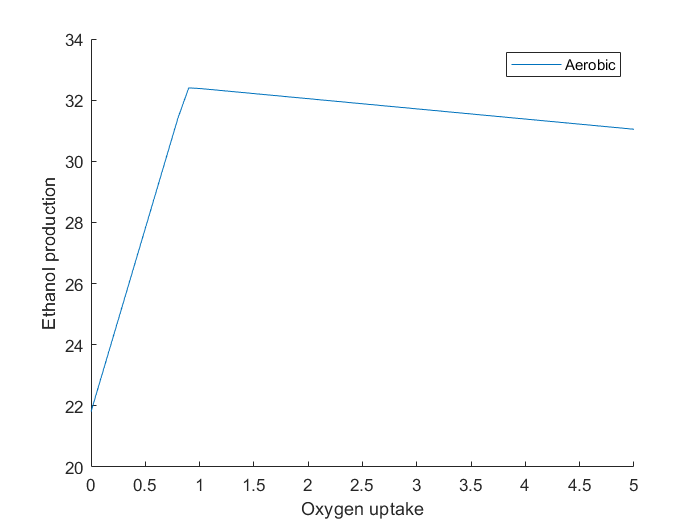

model=ecoli;
modelGlc = model;
modelGlc=changeRxnBounds(modelGlc,modelGlc.rxns(find(modelGlc.c)),0.5,'l'); %at least 0.4 for biomass
modelGlc=changeObjective(modelGlc,'EX_etoh(e)');
modelGlc = changeRxnBounds(modelGlc,'EX_glc(e)',-20,'b');
modelGlc = changeRxnBounds(modelGlc,'EX_o2(e)',-1000,'l');

EthanolProduction = [];%zeros(11,1);
steps=0:0.1:5;
i_c=0;
for i = steps
model = changeRxnBounds(modelGlc,'EX_o2(e)',-i,'b');
FBAsolution = optimizeCbModel(model,'max');
EthanolProduction(i_c+1) = FBAsolution.f;
i_c=i_c+1;
end

figure
hold on
plot(steps,EthanolProduction)
hold off
legend('Aerobic')
xlabel('Oxygen uptake')
ylabel('Ethanol production')

## Aerobic growth on glucose and ethanol production

model=ecoli;
modelGlc = model;
modelGlc=changeRxnBounds(modelGlc,modelGlc.rxns(find(modelGlc.c)),0.5,'l'); %at least 0.4 for biomass
modelGlc=changeObjective(modelGlc,'EX_etoh(e)');
modelGlc = changeRxnBounds(modelGlc,'EX_glc(e)',-20,'b');
modelGlc = changeRxnBounds(modelGlc,'EX_o2(e)',-1000,'l');
FBAsolutionGlc = optimizeCbModel(modelGlc,'max');
% options.zeroFluxWidth = 0.1;
% options.rxnDirMultiplier = 10;
% options.zeroFluxColor = [217 217 217]; %reactions with 0 flux are grey (RGB code)
% options.fileName='EcoliGlcO2_etoh.svg'; %file name of generated svg file
% options = drawFlux(map,modelGlc, FBAsolutionGlc.x,options); %function that places the fluxes (solution.x) on top of the map file and renders edges colored by the flux value